# 最小二乘小实验

## 一、 产生数据

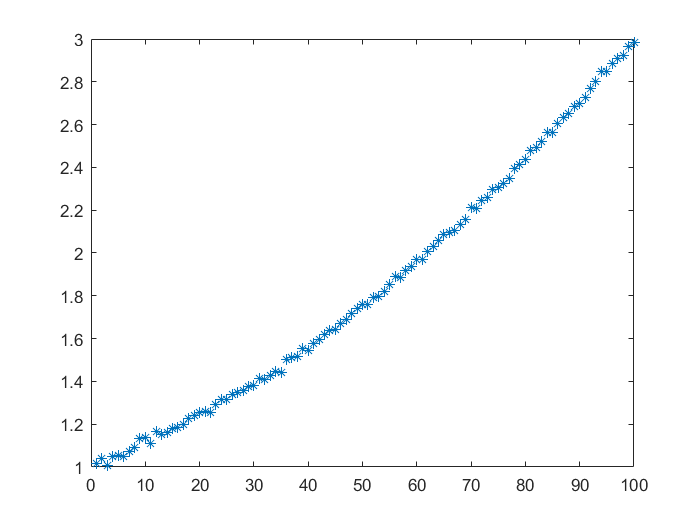

clear; clc;
% y(i) = 1 + x(i,1) + x(i,2) + e(i); e(i) 为随机正态噪声乘以0.01
x = [[0.01:0.01:1];[0.01:0.01:1].^2]';
rng(0,'twister');  % 产生可预测的随机数
y = [ones(100,1) x]*[1;[1 1]'] + 0.01*randn(100,1);
figure
plot(y,'*')

## 二、求解$\beta$

% 和文档一致
X = [ones(100,1) x]; Y = y;


$${\left(X^T X\right)}^{-1} X^T Y$$


% 直接解法
beta = inv(X'*X)*(X'*Y);  
disp(['Beta is   ', num2str(beta')])

Beta is   1.0064     0.98363      1.0092


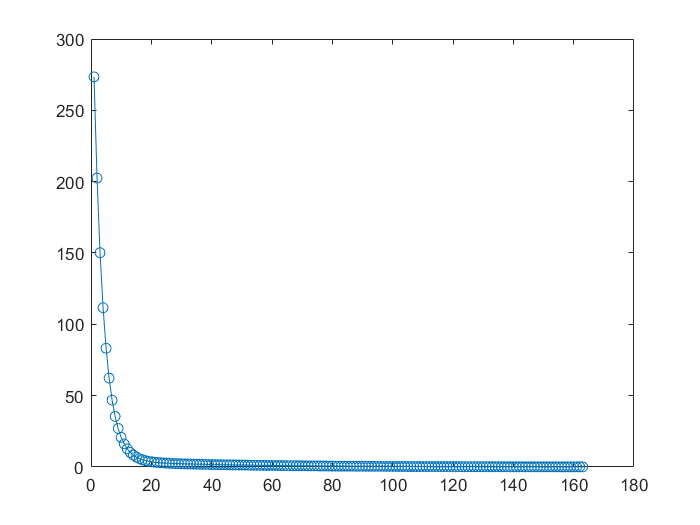


%% 梯度下降
%  初始化beta
beta = 0.01*rand(3,1);
% 初始化学习率 alpha
alpha = 0.001;
% 求负梯度方向
delta_beta = X'*Y - X'*X*beta;
new_beta = beta + alpha * delta_beta;
beta_list = [new_beta];

for i = 1 : 1000  % 最多迭代1000次
    loss(i) = norm(Y-X*new_beta)^2;
    if loss(i)<0.1
        break;
    else
        beta = new_beta;
        delta_beta = X'*Y - (X'*X)*beta;
        new_beta = beta + alpha * delta_beta;
        beta_list =[beta_list new_beta];
    end
end
plot(loss,'o-')

disp(['Beta is   ', num2str(new_beta')]) 

Beta is   1.0372      1.0199     0.88025


## 三、画梯度下降图

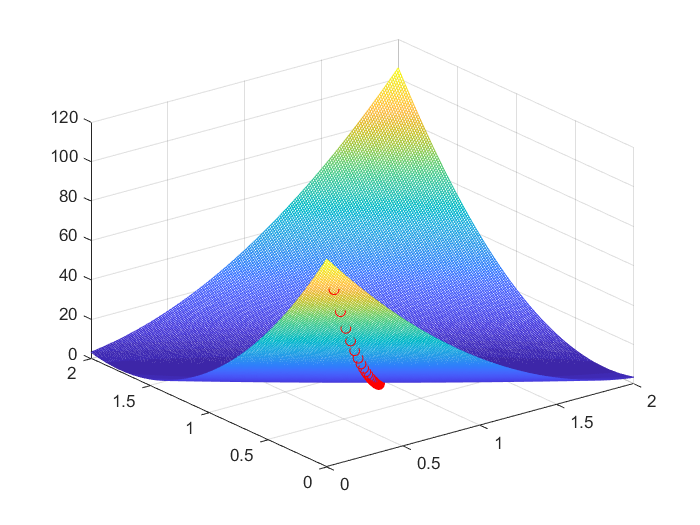

% 为了画图，我们固定beta(1) 为1，画x轴为beta(2)，y轴为beta(3)，z轴为norm(Y-X*beta)^2的图
% 并将每次迭代求得的值也画在图上
beta_1 = 0:0.01:2;
beta_2 = [0:0.01:2];
[B1,B2] = meshgrid(beta_1,beta_2);

for i = 1 : length(beta_1)
    for j = 1 : length(beta_2)
        Z(i,j) = norm(Y - ones(100,1)- x*[beta_1(i);beta_2(j)])^2;
    end
end
figure;
mesh(B1,B2,Z)
hold on
for i = 1 : length(beta_list)
    temp_b1(i) = beta_list(2,i);
    temp_b2(i) = beta_list(3,i);
    temp_n(i) = norm(Y - ones(100,1)- x*[beta_list(2,i);beta_list(3,i)])^2;
end

plot3(temp_b1,temp_b2,temp_n,'ro');